## Methode 1 = hijsen pickup .

### UPWARDS MOTION =  GAINED POTENTIAL ENERGY

xi = 0; xe =100; yi = 150;ye =120;
g = 9.81;
m = 5;%   needs to be the weight of the crate
dEpot1 = (m*g*yi - m*g*ye)/100

dEpot1 = 14.7150

### MOVEMENT HORIZONTAL TO THE RIGHT

g = 9.81;
l = 1.5;
omega = 2*pi*sqrt(l/g);
periode = vpa(2*pi/omega,3) % in seconde 

$$periode = 2.56$$


% impuls 1 of speed is a triangle for 0-20cm/s in 1 second <]
% impuls 2 is the same but with a negative slope [>  


v_max= 20; %cm/s
dx = 1*v_max / 2 * 2 % cm moved by impulses

dx = 20


x_resting = 100 - dx;
resting_time  = x_resting/v_max;
total_time = 2 + resting_time;


period_time = round((periode*100))

$$period\_time = 256$$

%period_time = 628
impulse_time = 50; % ms
end_time = period_time + impulse_time;


time_1 = (0:2:impulse_time-1)/100;
time_1(end)

ans = 0.4800

time_2 = (impulse_time:2:period_time)/100;
time_2(end)

$$ans = \frac{64}{25}$$

time_3 = (period_time:2:end_time)/100;
time_3(end)

$$ans = \frac{153}{50}$$

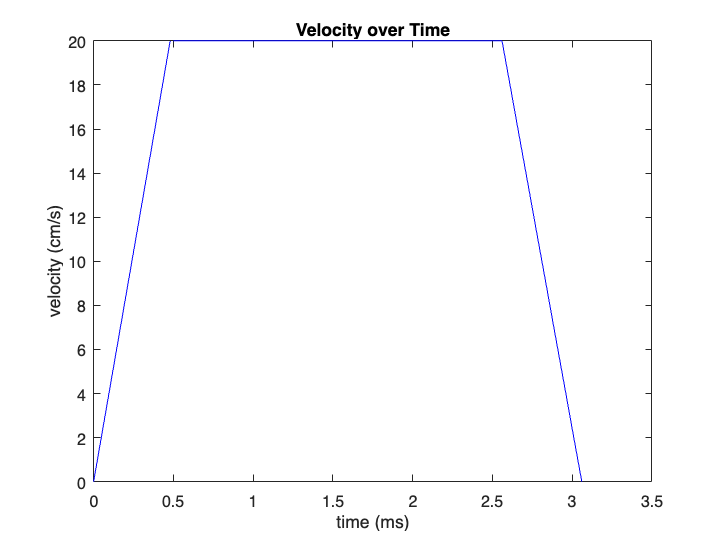


figure
plot(time_1,(0:v_max/(length(time_1)-1):v_max),'b')
hold on 
plot(time_2,(ones(length(time_2))*v_max),'b');
plot(time_3,(v_max:-v_max/(length(time_3)-1):0),'b')
hold off
title('Velocity over Time')
xlabel('time (ms)')
ylabel('velocity (cm/s)')

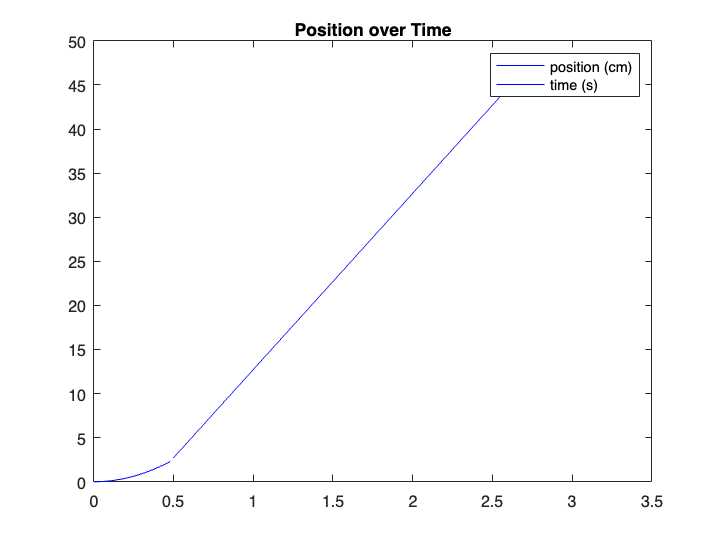


int1 = v_max/2*time_1(end).^2;
int2 = v_max*(time_2(end)- time_1(end));

plot(time_1, v_max/2*(time_1).^2, 'b')
hold on 
plot(time_2, v_max*(time_2 - time_1(end)) + v_max/2*time_1(end).^2 , 'b');
plot(time_3, v_max/2*(time_2(end).^2-time_3.^2) + end_time/100*v_max*(time_3-time_2(end)) +int1 +int2, 'b');
hold off
title('Position over Time')
legend('position (cm)', 'time (s)')

schrijven naar csv file: 

array_1 = 0:v_max/(length(time_1)-1):v_max;
array_2 = ones(1,length(time_2))*v_max;
array_3 = v_max:-v_max/(length(time_3)-1):0;
combined_array = [array_1, array_2, array_3];
file_name = 'input_shaping_100cm_20cm_s_50hz.csv';
csvwrite(file_name, combined_array)


## Methode 2: Swing const CL

### SWING MOVEMENT WITH RAMP VELOCITY

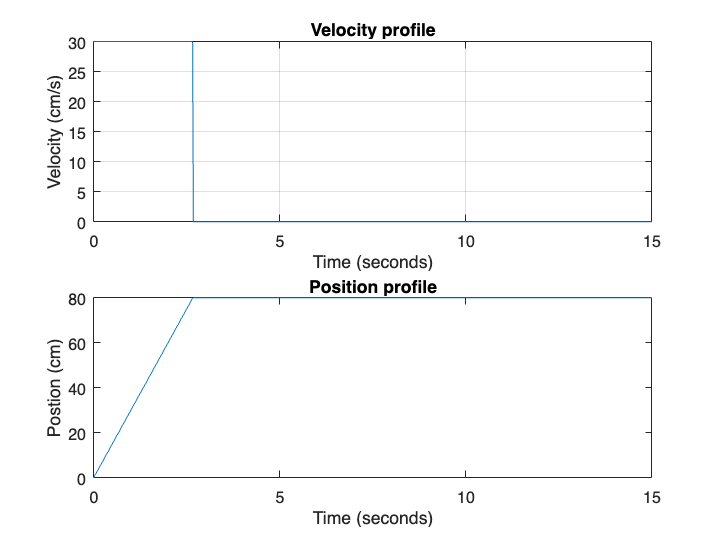

file_name_1 = "ramp_velocity.csv";
data_1 = csvread(file_name_1);
file_name_2 = "ramp_position.csv";
data_2 = csvread(file_name_2);
% Calculate time scale
sampling_rate = 50; % Frequency in Hz
time_interval = 1 / sampling_rate;
time_seconds = (0:numel(data_1)-1) * time_interval; % Time in seconds

figure
% Plot the velocity profile on a time scale
subplot(2,1,1)
plot(time_seconds, data_1*100);
title('Velocity profile');
xlabel('Time (seconds)');
ylabel('Velocity (cm/s)');
grid on;
subplot(2,1,2)
plot(time_seconds, data_2*100);
title('Position profile');
xlabel('Time (seconds)');
ylabel('Postion (cm)');

## Methode 3: Swing initial angle and variable CL

Here we are using an impulse while under angle to create a higher amplitude of the angle and we shorten the cable with a function in c createPath that gives x_m the middle position and also gives the speed profile for the cable length.

Ones we arrive in xm,  the motor starts an impuls to the right and shortens the cable simultaneous to create a large amplitude of the angle. 

### STARTING UNDER AN ANGLE

g = 9.81;
l = 1.5;
omega_swing = 2*pi*sqrt(l/g);
starting_angle = 24; % degreess
periode_swing = vpa(2*pi/(2*omega_swing),3)

$$periode\_swing = 1.28$$

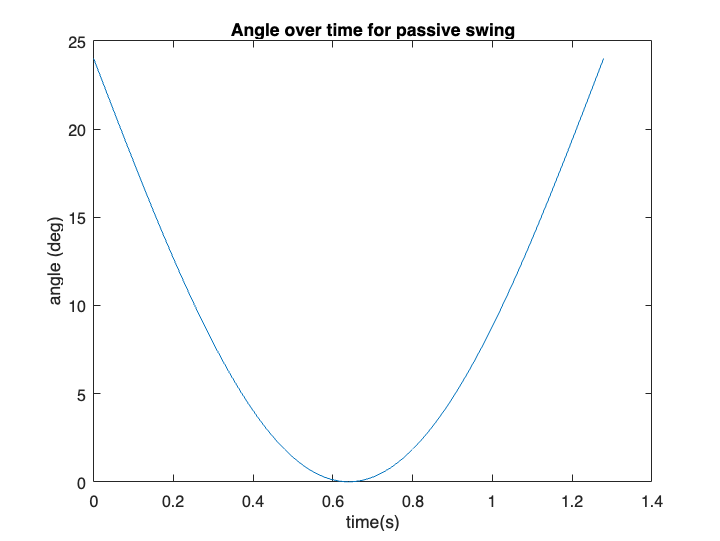

t = linspace(0,periode_swing,1000);
figure
plot(t,starting_angle*(1-sin(omega_swing*t)))
xlabel("time(s)")
ylabel("angle (deg)")
title("Angle over time for passive swing")

Here is just the profile of the angle of a passive swing, because we add energy by moving to the right in short interval as an `impulse`.  This creates the superposition of the two. 

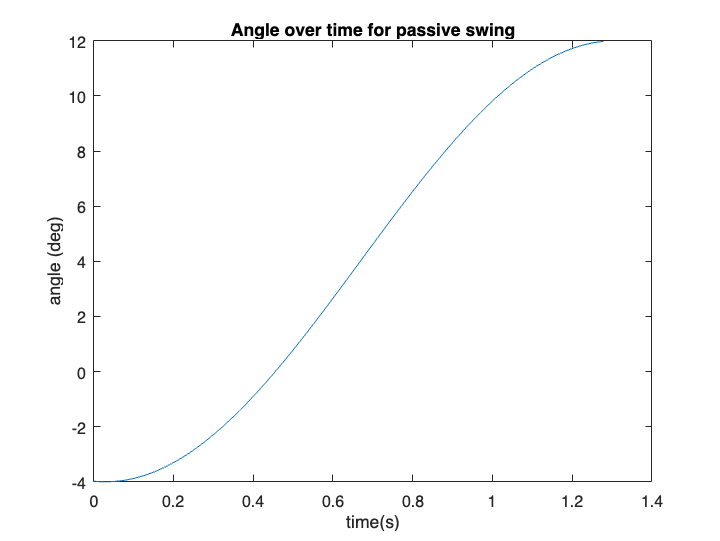

figure
plot((t),8*(0.5-sin(omega_swing*(t+0.61))))
xlabel("time(s)")
ylabel("angle (deg)")
title("Angle over time for passive swing")

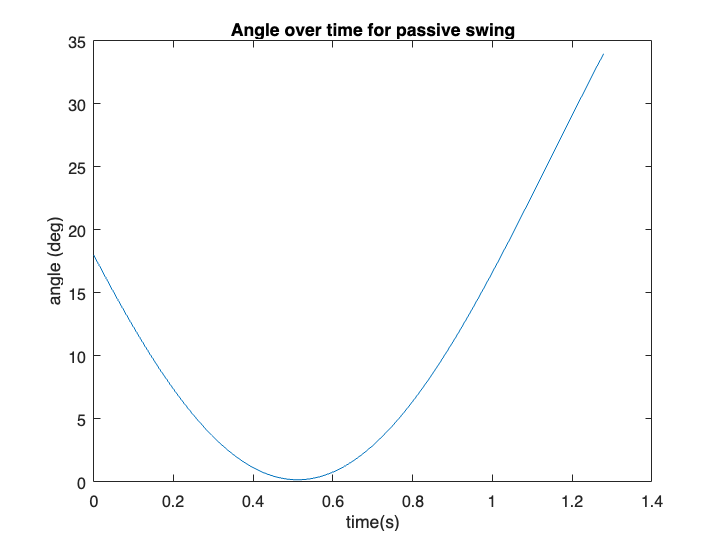



figure
plot((t),(starting_angle*(1-sin(omega_swing*t)) + 8*(0.5-sin(omega_swing*(t+0.61))))-2)
xlabel("time(s)")
ylabel("angle (deg)")
title("Angle over time for passive swing")